### Hankel alternative view of koopman

This is the full follow up from the first file where we did experiments with hankel completion. From here we will try to compute the next point using HAVOK.

clear all, close all, clc
addpath('./utils');
% Example time series data
data = sin(0.1 * (1:100000))' + 0.05 * randn(100000, 1);
dataLength = length(data);
L = 25;  % Number of lags (rows in the Hankel matrix)
N = dataLength - L + 1;  % Total columns in the Hankel matrix

% Create the full Hankel matrix without missing values initially
HankelMatrix = hankel(data(1:L), data(L:end));

% Define the number of points we want to predict (missing at the end)
numPredict = 0;

% Create a logical mask for the Hankel matrix with all ones (no missing data)
mask = true(size(HankelMatrix));

% Identify the columns in the Hankel matrix that correspond to the last 'numPredict' points
% These points appea5r in the last 'numPredict' rows of the last columns
for i = 1:numPredict
    mask(end-i+1, end-numPredict+i:end) = false;
end

% Now, apply the mask to set the last 'numPredict' points as NaN (missing)
HankelMatrix(~mask) = NaN;

% Display the mask and modified Hankel matrix to check
disp(mask);

  Columns 1 through 8.191

   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1 

tspan = transpose(1:1:size(data,1));
xdat = data(:,1)-mean(data(:,1));

dt = tspan(2)-tspan(1);

lag = 25;
rmax = 5;

Now we make the hankel matrix of the attractor when I increase shift-back number

clear V, clear dV
[U,S,V] = svd(HankelMatrix,'econ');
sigs = diag(S);
beta = size(HankelMatrix,1)/size(HankelMatrix,2);
thresh = optimal_SVHT_coef(beta,0) * median(sigs);
r = length(sigs(sigs>thresh))

r = 2

r=min(rmax,r)

r = 2

Now to discrete time:

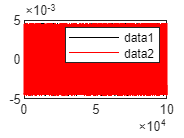

x = V(1:end-1,1:r);
xprime = V(2:end,1:r);

Xi = xprime\x;
B = Xi(1:r-1,r);
A = Xi(1:r-1,1:r-1);
sys = ss(A,B,eye(r-1),0*B,dt);

L = 1:size(x,1);
[y,t] = lsim(sys,x(L,r),dt*(L-1),x(1,1:r-1));
plot(V(:,1),'k')
hold on
plot(y(:,1),'r')
legend('show')

## Part 2: Time Series

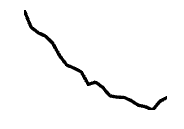

figure
tspan = dt:dt:dt*length(xdat);
plot(tspan,xdat(:,1),'k','LineWidth',2)
set(gca,'XTick',[0 10 20 30 40 50],'YTick',[-20 -10 0 10 20])
set(gcf,'Position',[100 100 2*250 2*175])
axis off
xlim([30 50])

% print('-depsc2', '-loose', [figpath,ModelName,'_p2.eps']);

## Part 3: Embedded Attractor

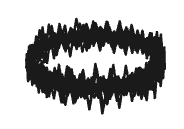

figure
L = 1:900;
plot3(V(L,1),V(L,2),V(L,3),'Color',[.1 .1 .1],'LineWidth',1.5)
set(gca,'XTick',[],'YTick',[],'ZTick',[])
axis tight
axis off
view(-92,47)
set(gcf,'Position',[100 100 3*250 3*175])

set(gcf,'PaperPositionMode','auto')
% print('-depsc2', '-loose', [figpath,ModelName,'_p3.eps']);

## Part 4: Model Time Series

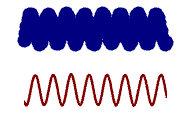

xmin = 200;
xmax = 700;
L = xmin:xmax;
L2 = xmin:5:xmax;
figure
subplot(2,1,1)
plot(L,x(L,1),'Color',[.4 .4 .4],'LineWidth',2.5)
hold on
plot(L2,y(L2,1),'.','Color',[0 0 .5],'LineWidth',10,'MarkerSize',25)
xlim([xmin xmax])
box off, axis off
subplot(2,1,2)
plot(L,x(L,r),'Color',[.5 0 0],'LineWidth',1.5)
xlim([xmin xmax])
box off, axis off
set(gcf,'Position',[100 100 2*250 2*175])

set(gcf,'PaperPositionMode','auto')
% print('-depsc2', '-loose', [figpath,ModelName,'_p4.eps']);

## Part 5: Reconstructed Attractor

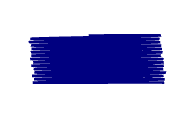

figure
L = 1:900;
plot(y(L,1),'Color',[0 0 .5],'LineWidth',1.5)
axis tight
axis off
view(-92,47)
set(gcf,'Position',[100 100 3*250 3*175])

set(gcf,'PaperPositionMode','auto')
% print('-depsc2', '-loose', [figpath,ModelName,'_p5.eps']);

## Part 6: Forcing Statistics

figure
Vtest = std(V(:,r))*randn(200000,1);
[h,hc] = hist(V(:,r)-mean(V(:,r)),[-.02:.005:.02]);%[-.03  -.02 -.015  -.0125 -.01:.0025:.01 .0125  .015 .02  .03]);
[hnormal,hnormalc] = hist(Vtest-mean(Vtest),[-.02:.005:.02])

hnormal =            0           4        1809       41242      113704       41459        1776           6           0


hnormalc =    -0.0200   -0.0150   -0.0100   -0.0050         0    0.0050    0.0100    0.0150    0.0200


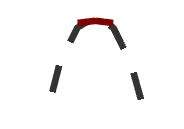

semilogy(hnormalc,hnormal/sum(hnormal),'--','Color',[.2 .2 .2],'LineWidth',4)
hold on
semilogy(hc,h/sum(h),'Color',[0.5 0 0],'LineWidth',4)
ylim([.0001 1])
xlim([-.02 .02])
axis off
set(gcf,'Position',[100 100 2*250 2*175])

set(gcf,'PaperPositionMode','auto')
% print('-depsc2', '-loose', [figpath,ModelName,'_p6.eps']);

## Part 7: U Modes

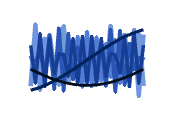

figure
CC = [2 15 32;
    2 35 92;
    22 62 149;
    41 85 180;
    83 124 213;
    112 148 223;
    114 155 215];
plot(U(:,1:r),'Color',[.5 .5 .5],'LineWidth',1.5)
hold on
for k=7:-1:1
    plot(U(:,k),'linewidth',1.5+2*k/10,'Color',CC(k,:)/255)
end
axis off
set(gcf,'Position',[100 100 2*250 2*175])

set(gcf,'PaperPositionMode','auto')
% print('-depsc2', '-loose', [figpath,ModelName,'_p7.eps']);

## PART 8: PREDICT WAVE

L = 1:length(V);
inds = V(L,r).^2>1.e-5;
L = L(inds);
startvals = [];
endvals = [];
start = 165;
clear interval hits endval newhit
numhits = 342;
for k=1:numhits;
    k
    startvals = [startvals; start];
    endmax = start+50;
    interval = start:endmax;
    hits = find(inds(interval));
    endval = start+hits(end);
    endvals = [endvals; endval];
    newhit = find(inds(endval+1:end));
    start = endval+newhit(1);
end

k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 50

k = 51

k = 52

k = 53

k = 54

k = 55

k = 56

k = 57

k = 58

k = 59

k = 60

k = 61

k = 62

k = 63

k = 64

k = 65

k = 66

k = 67

k = 68

k = 69

k = 70

k = 71

k = 72

k = 73

k = 74

k = 75

k = 76

k = 77

k = 78

k = 79

k = 80

k = 81

k = 82

k = 83

k = 84

k = 85

k = 86

k = 87

k = 88

k = 89

k = 90

k = 91

k = 92

k = 93

k = 94

k = 95

k = 96

k = 97

k = 98

k = 99

k = 100

k = 101

k = 102

k = 103

k = 104

k = 105

k = 106

k = 107

k = 108

k = 109

k = 110

k = 111

k = 112

k = 113

k = 114

k = 115

k = 116

k = 117

k = 118

k = 119

k = 120

k = 121

k = 122

k = 123

k = 124

k = 125

k = 126

k = 127

k = 128

k = 129

k = 130

k = 131

k = 132

k = 133

k = 134

k = 135

k = 136

k = 137

k = 138

k = 139

k = 140

k = 141

k = 142

k = 143

k = 144

k = 145

k = 146

k = 147

k = 148

k = 149

k = 150

k = 151

k = 152

k = 153

k = 154

k = 155

k = 156

k = 157

k = 158

k = 159

k = 160

k = 161

k = 162

k = 163

k = 164

k = 165

k = 166

k = 167

k = 168

k = 169

k = 170

k = 171

k = 172

k = 173

k = 174

k = 175

k = 176

k = 177

k = 178

k = 179

k = 180

k = 181

k = 182

k = 183

k = 184

k = 185

k = 186

k = 187

k = 188

k = 189

k = 190

k = 191

k = 192

k = 193

k = 194

k = 195

k = 196

k = 197

k = 198

k = 199

k = 200

k = 201

k = 202

k = 203

k = 204

k = 205

k = 206

k = 207

k = 208

k = 209

k = 210

k = 211

k = 212

k = 213

k = 214

k = 215

k = 216

k = 217

k = 218

k = 219

k = 220

k = 221

k = 222

k = 223

k = 224

k = 225

k = 226

k = 227

k = 228

k = 229

k = 230

k = 231

k = 232

k = 233

k = 234

k = 235

k = 236

k = 237

k = 238

k = 239

k = 240

k = 241

k = 242

k = 243

k = 244

k = 245

k = 246

k = 247

k = 248

k = 249

k = 250

k = 251

k = 252

k = 253

k = 254

k = 255

k = 256

k = 257

k = 258

k = 259

k = 260

k = 261

k = 262

k = 263

k = 264

k = 265

k = 266

k = 267

k = 268

k = 269

k = 270

k = 271

k = 272

k = 273

k = 274

k = 275

k = 276

k = 277

k = 278

k = 279

k = 280

k = 281

k = 282

k = 283

k = 284

k = 285

k = 286

k = 287

k = 288

k = 289

k = 290

k = 291

k = 292

k = 293

k = 294

k = 295

k = 296

k = 297

k = 298

k = 299

k = 300

k = 301

k = 302

k = 303

k = 304

k = 305

k = 306

k = 307

k = 308

k = 309

k = 310

k = 311

k = 312

k = 313

k = 314

k = 315

k = 316

k = 317

k = 318

k = 319

k = 320

k = 321

k = 322

k = 323

k = 324

k = 325

k = 326

k = 327

k = 328

k = 329

k = 330

k = 331

k = 332

k = 333

k = 334

k = 335

k = 336

k = 337

k = 338

k = 339

k = 340

k = 341

k = 342

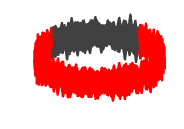

%
figure
for k=155:302%1:numhits
    plot3(V(startvals(k):endvals(k),1),V(startvals(k):endvals(k),2),V(startvals(k):endvals(k),3),'r','LineWidth',1.5), hold on
end
for k=155:302%1:numhits-1
    plot3(V(endvals(k):startvals(k+1),1),V(endvals(k):startvals(k+1),2),V(endvals(k):startvals(k+1),3),'Color',[.25 .25 .25],'LineWidth',1.5), hold on
end
axis tight
axis off
view(-92,47)
set(gcf,'Position',[100 100 3*250 3*175])

set(gcf,'PaperPositionMode','auto')
% print('-depsc2', '-loose', [figpath,ModelName,'_p8_3D.eps']);